# Lab 7 - Event selection optimization

Thomas Conaway

Lab Partners: Avi Soval, Jeff Jiang

clc; clear; close all;
% signal dataset is labelled higgs, background dataset is labeled "qcd"
% h5disp("higgs_100000_pt_1000_1200.h5");
% h5disp("qcd_100000_pt_1000_1200.h5");
signaldata1 = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
bgdata1 = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

## Problem 1

Stacked histogram for the mass feature variable, normalized to expected yields of 50 for Higgs and 2000 for the QCD:

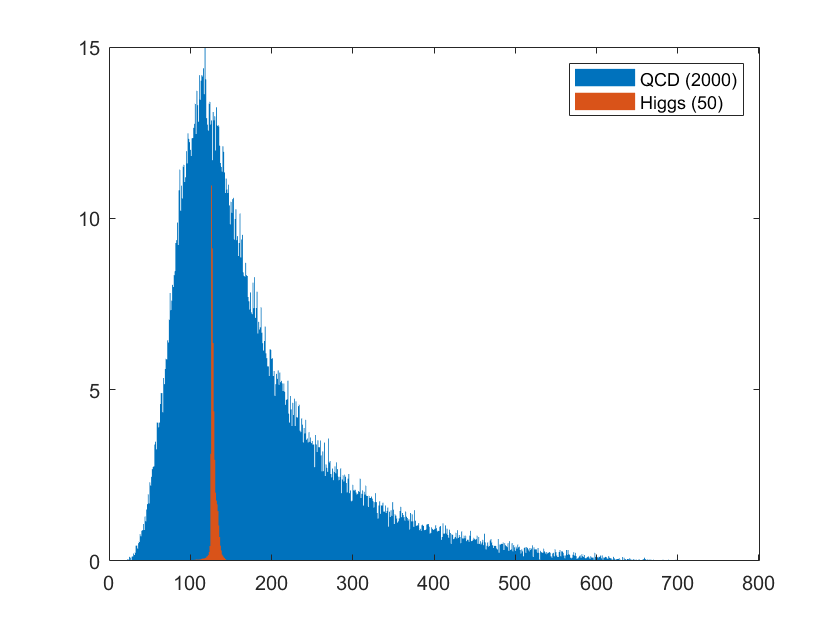

signal = signaldata1(4,:);
bg = bgdata1(4,:);
x = 0:1:800; % finer steps for bin size results in sharper Higgs peak
figure("Visible","off");
h = histogram(signal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
hold on;
h2 = histogram(bg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
hold off;
f1 = figure();
figure(f1);
% can use the following to properly "stack" bars
% y = [h2.BinCounts;h.BinCounts];
% bar(h2.BinEdges(2:end),y.','stacked',"Edgecolor","none","BarWidth",1); 
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (2000)","Higgs (50)");
hold off;

Higgs distribution is very sharply peaked at 125 MeV. When collecting, we would see the combined QCD and Higgs distribution, with this jutting out. In the next lab (Lab 8) we can see this appear in our high luminosity data.

Using Poisson statistics for significance calculation (*do significance calculation using poisson with a mean of the expected value). I spoke with Olivia at the end of our last lab to try to clarify what exactly was meant by "mean of the expected value". I had originally thought the significance calculation would come from the data distribution that corresponds to the stacked histogram above, but this instead meant the expected values 2000, 50, and their sum 2050, which we use as the mean for our calculation.

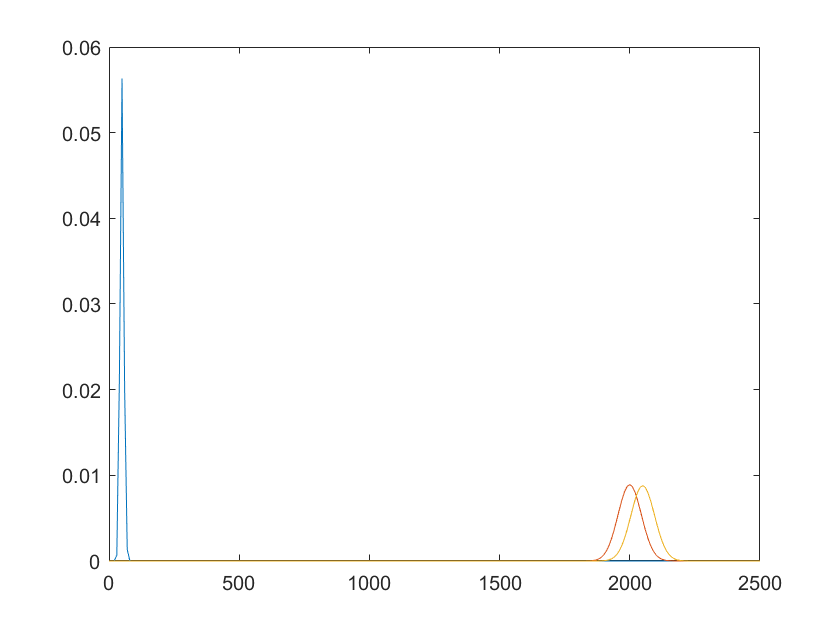

disthiggs = makedist("Poisson","lambda",50);
distqcd = makedist("Poisson","lambda",2000);
distcombo = makedist("Poisson","lambda",2050);
x = 0:10:2500;
plot(x,pdf(disthiggs,x));
hold on;
plot(x,pdf(distqcd,x));
plot(x,pdf(distcombo,x));
hold off;

Significance as I understand it should refer to the probability of background producing the event. It's not immediately clear what we should be looking for here. When we run this experiment we expect to see, for 2050 total events, 2000 background and 50 Higgs. Are we looking for the probability of the background producing 50 Higgs detections, or something else?

Significance calculation:

prob = cdf(distqcd,2050,'upper'); % this produces a value close to higgs/sqrtbg, but I don't know why
sigma = abs(norminv(prob))

sigma = 1.1282

% original significance calculation
prob2 = cdf(makedist("Poisson","lambda",118),125,'upper');
sigma2 = abs(norminv(prob2))

sigma2 = 0.6985

Comparison to $N_{\mathrm{Higgs}} \;/\sqrt{\;N_{\mathrm{QCD}} }$:

50/sqrt(2000)

ans = 1.1180

These two values should be equivalent. The purpose of this making this comparison is to show that this new expression can also be used to calculate significance.

## Problem 2

We will first try cutting below 100 and above 145, because this preserves almost all of the Higgs data while making significant cuts to the background.

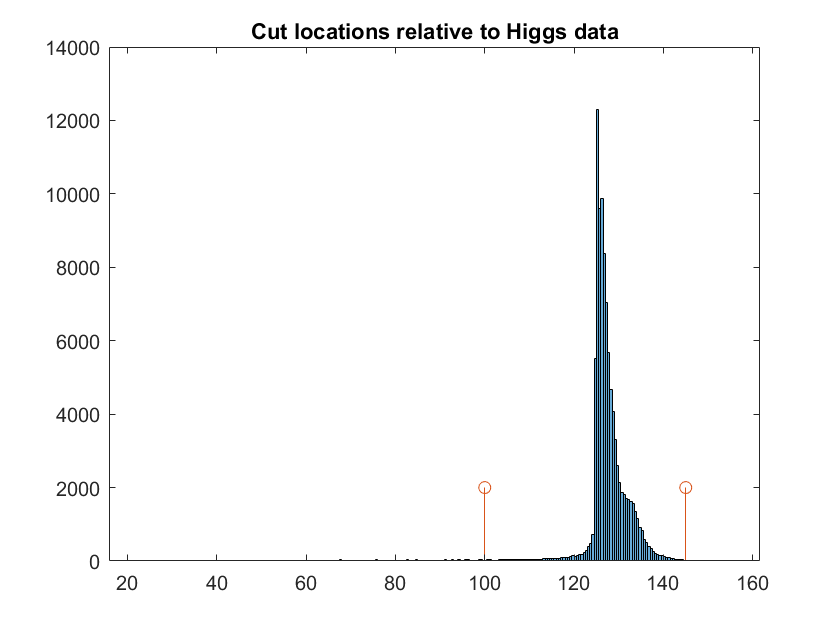

lowercut = 100;
uppercut = 145;
histogram(signal);
hold on;
stem([lowercut,uppercut],[2000,2000]);
title("Cut locations relative to Higgs data")
hold off;

% removing data that falls outside cuts
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);
% re-normalizing the cut signal to the expected yields. Example: if we
% expect 50 Higgs and our cut removes half the area of their distribution, we now expect to now hold
% onto only 25 Higgs. The fraction of the data remaining multiplied the normalization factor will
% give us this because the un-normalized area of the histogram gives the
% total count, so a faction of the counts is a fraction of the area.
nhiggs = numel(cutsignal)/numel(signal)*50

nhiggs = 48.9905

nqcd = numel(cutbg)/numel(bg)*2000

nqcd = 573.8200

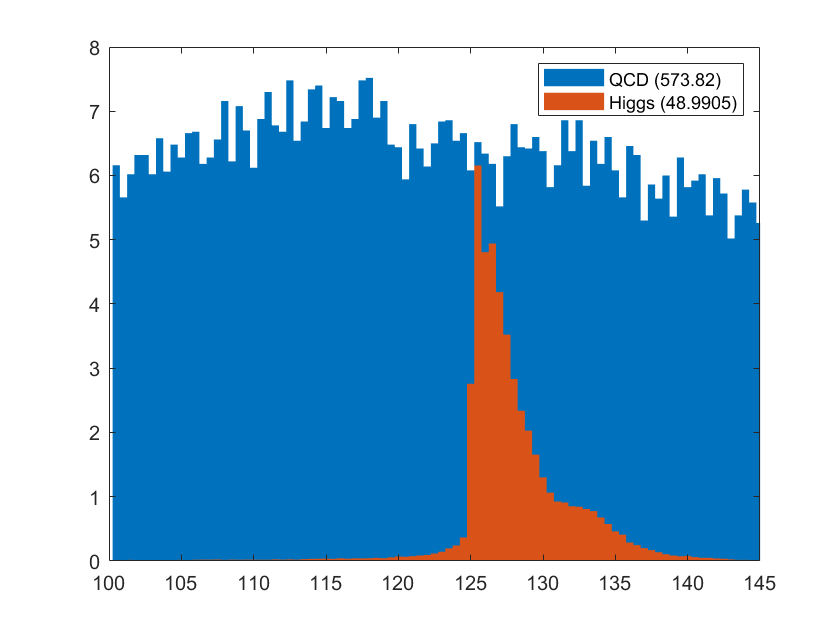


% re-plotting stacked histogram to see changes
figure("Visible","off");
x = lowercut:0.5:uppercut;
h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;
f1 = figure();
figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
xlim([lowercut,uppercut]);
hold off;

nhiggs/sqrt(nqcd)

ans = 2.0451

The significance has increased. With this cut we remove nearly three-quarters of the QCD background while preserving almost all of our Higgs.

We will try moving inward towards 125, starting with cuts at 124 and 130.

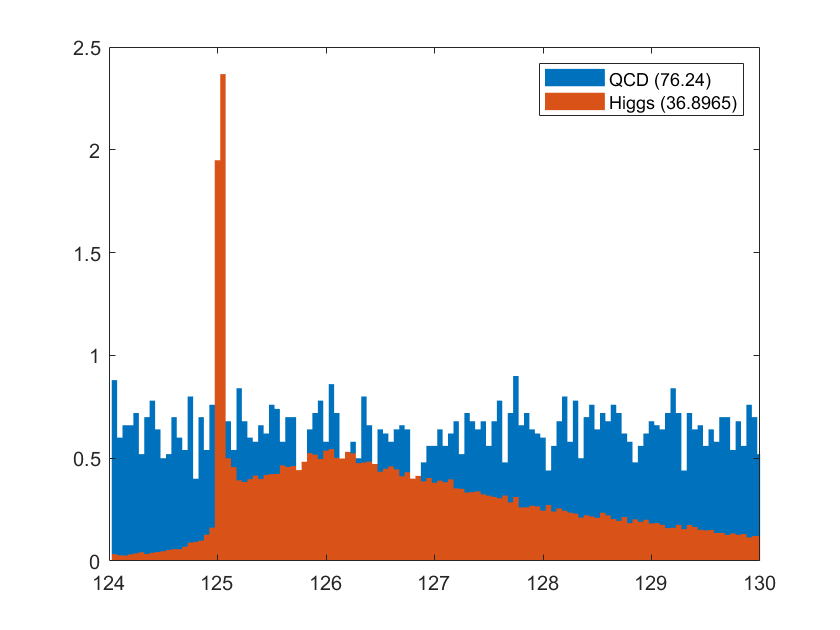

lowercut = 124;
uppercut = 130;
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);
nhiggs = numel(cutsignal)/numel(signal)*50;
nqcd = numel(cutbg)/numel(bg)*2000;

% plotting again:
figure("Visible","off");
x = lowercut:0.05:uppercut;
h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;
f1 = figure();
figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
xlim([lowercut,uppercut]);
hold off;

nhiggs/sqrt(nqcd)

ans = 4.2257

The significance has increased yet again. Over this range the Higgs compose nearly a third of the data we collect. 

We will now try cutting very, very close to 125.

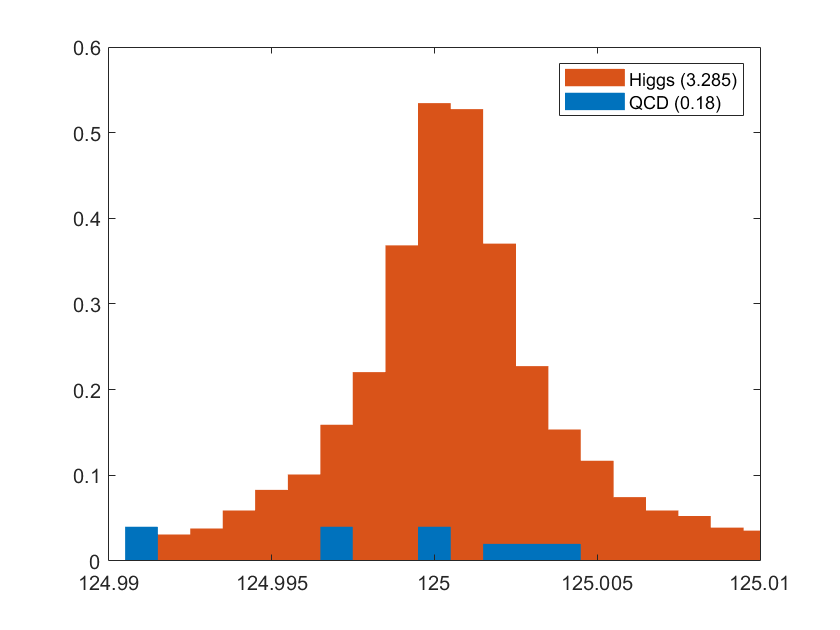

lowercut = 124.99;
uppercut = 125.01;
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);
nhiggs = numel(cutsignal)/numel(signal)*50;
nqcd = numel(cutbg)/numel(bg)*2000;

figure("Visible","off");
x = lowercut:0.001:uppercut;
h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;
f1 = figure();
figure(f1);
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
hold on;
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
legend("Higgs (" + nhiggs + ")","QCD (" + nqcd + ")");
xlim([lowercut,uppercut]);
hold off;

nhiggs/sqrt(nqcd)

ans = 7.7428

Cut datasets with the highest significance are the ones trimmed closest to the mass value of 125. This may not mean anything because there are now gaps in the background distribution, so we're approaching the point where this counting method runs into trouble as it becomes possible to select cut regions with no background data within. We may need to rethink this approach and think purely in terms of distribution curve because the granularity is an issue. I was also told that cutting cutting just the mass will not result in significance greater than 1, so there may be something wrong with the method I am using.

I played around with some values and the highest I found was 7.7428 for when lower cut is 124.99 and upper cut is 125.01.

Nearly all of the QCD has been removed (this narrow slice of the QCD distribution contains very few of the 2000 expected). Most of the Higgs have also been lost. This granularity will create issues in Lab 8 because the sets of data have fewer points to work with, so we may risk losing information about the distribution if they happen to not fall often enough into the narrow range. Moving forward with this lab, I will try to preserve as much of the signal as I possibly can by selecting other features to cut around.

## Problem 3

Stacked plots for the rest of the features:

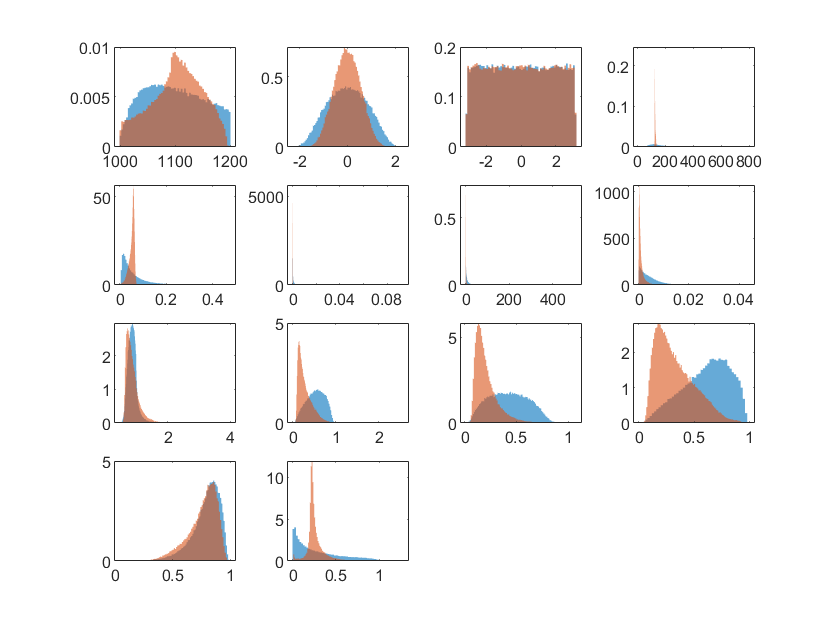

% to normalize or not normalize so as to show features at a glance? doing
% the 50 2000 thing makes them difficult to examine

% with standard normalization:
close all hidden;
for k = 1:14
    subplot(4,4,k);
    histogram(bgdata1(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold on;
    histogram(signaldata1(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold off;
end

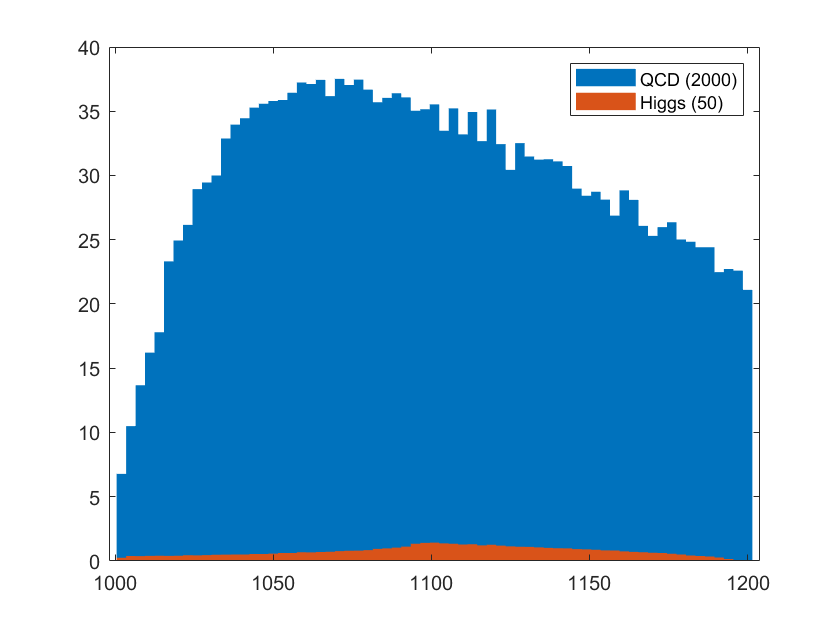

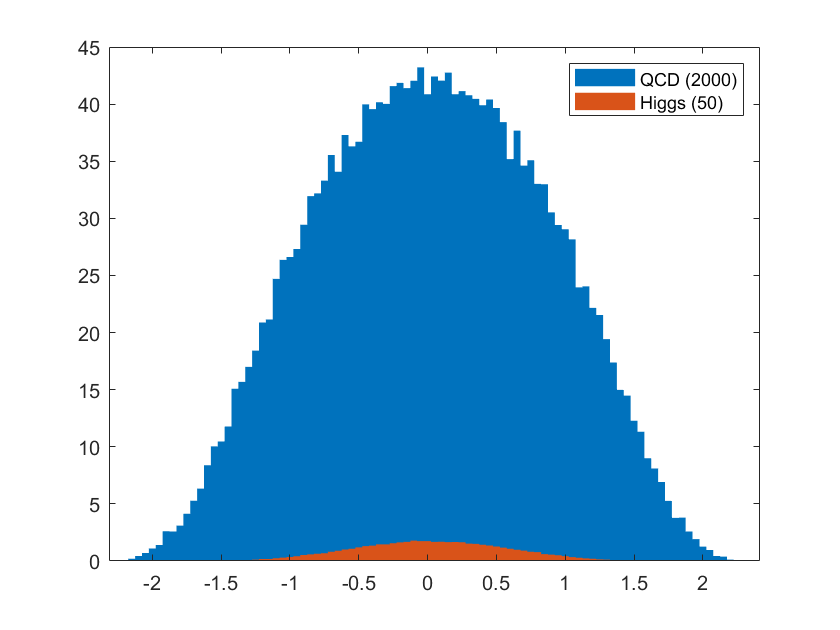

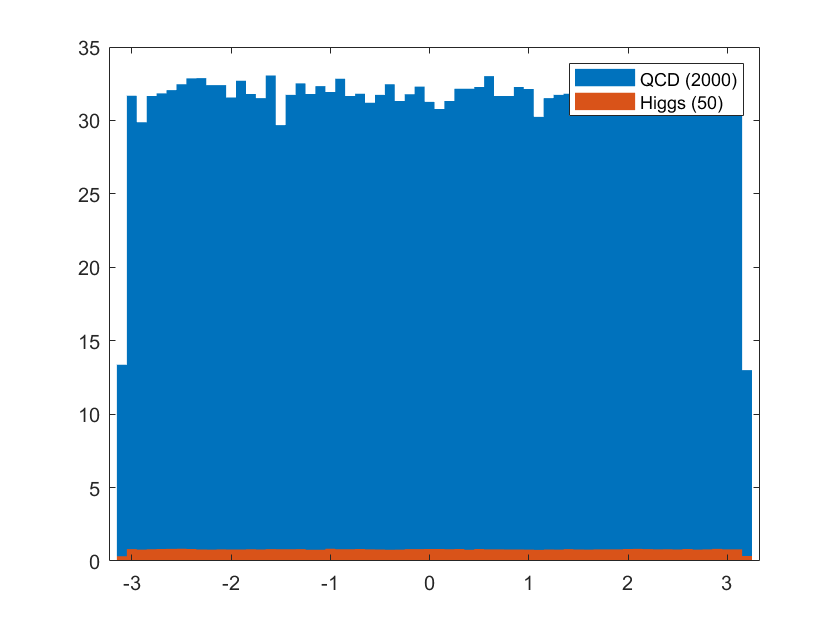

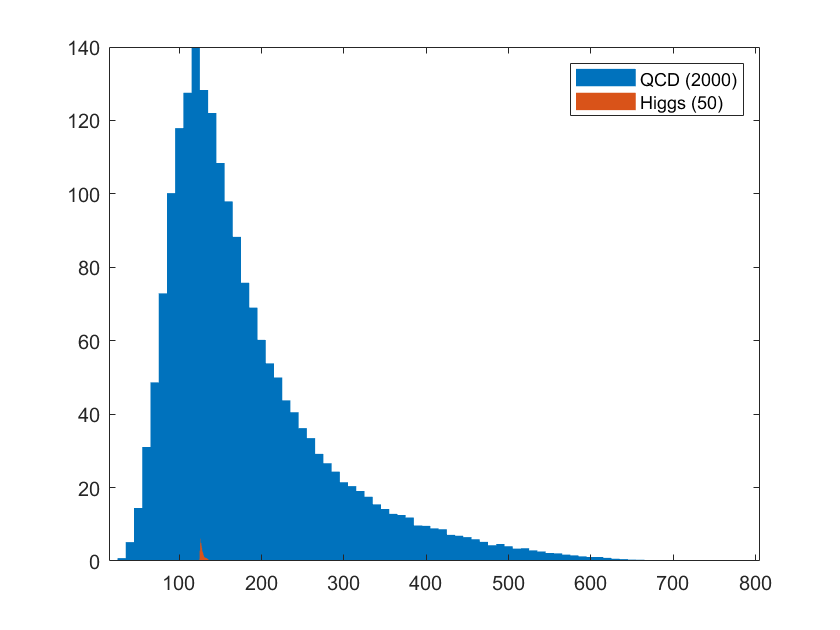

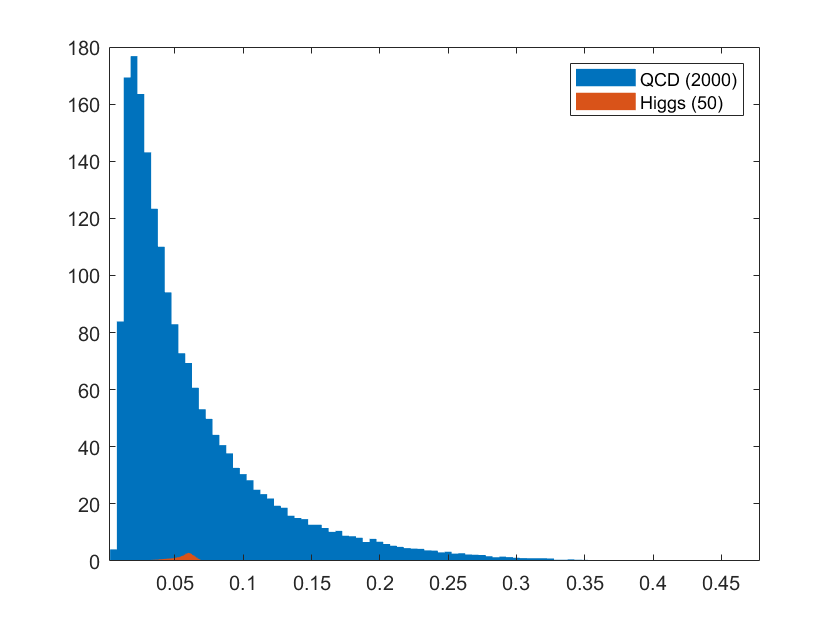

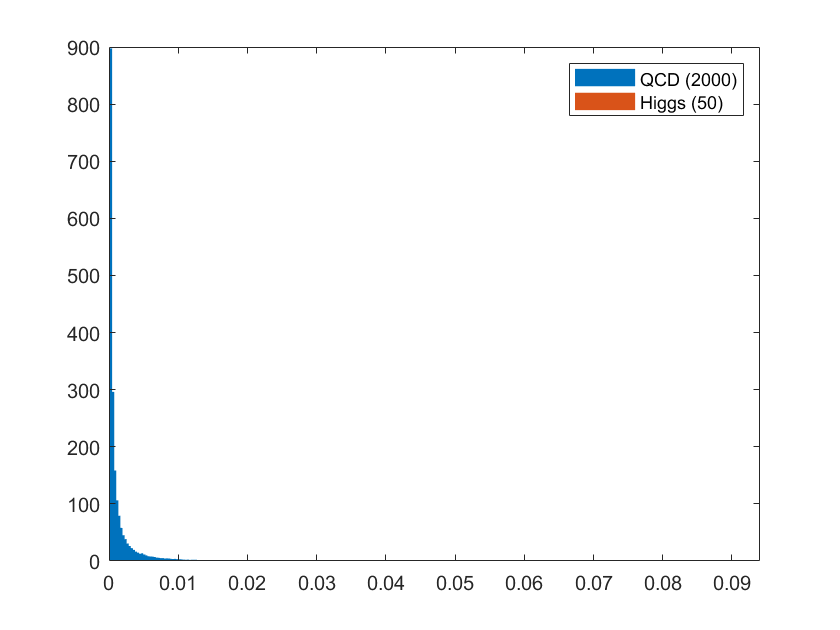

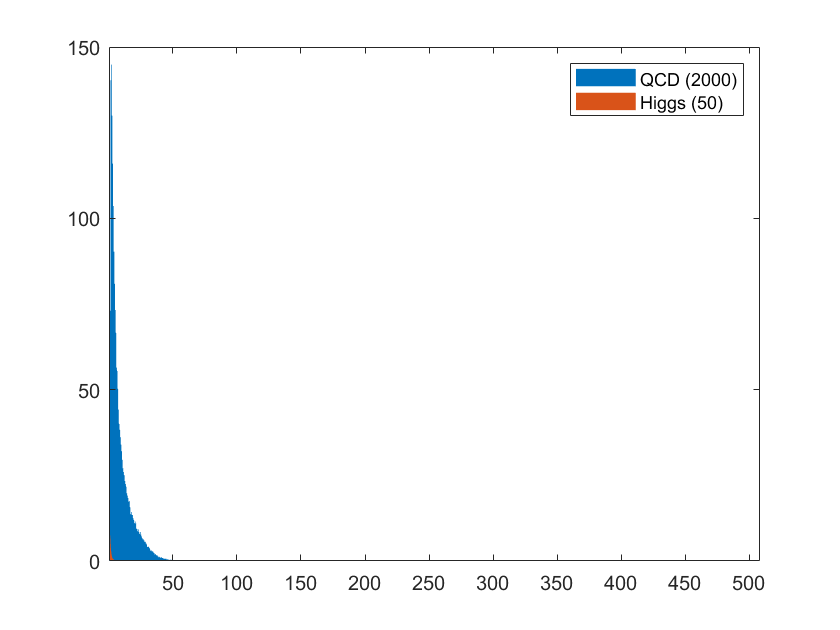

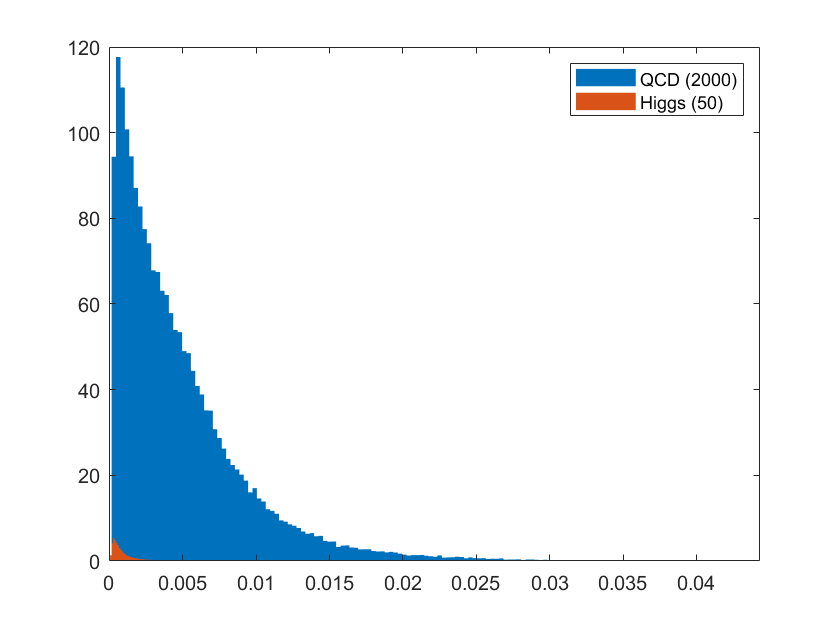

% these are with 50 2000 normalization:
for k = 1:14
    signal = signaldata1(k,:);
    bg = bgdata1(k,:);
    f1 = figure();
    f2 = figure("Visible","off");
    h = histogram(signal,"Normalization","pdf");
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
    hold on;
    h2 = histogram(bg,"Normalization","pdf");
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
    hold off;
    
    %subplot(4,4,k);
    figure(f1);
    bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
    hold on;
    bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
    legend("QCD (2000)","Higgs (50)");
    hold off;
end

It would appear that there are a number of features that could make for good cuts, such as in ???.

Set B:

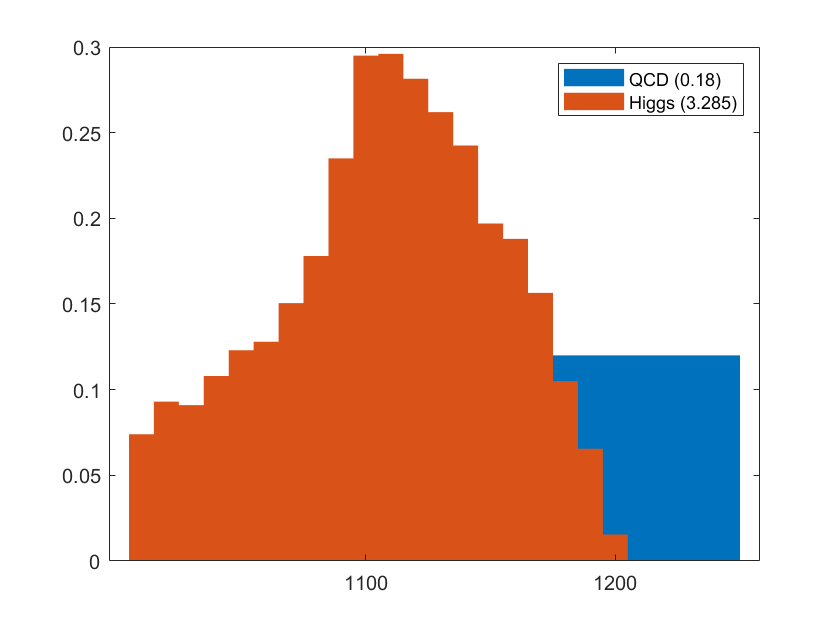

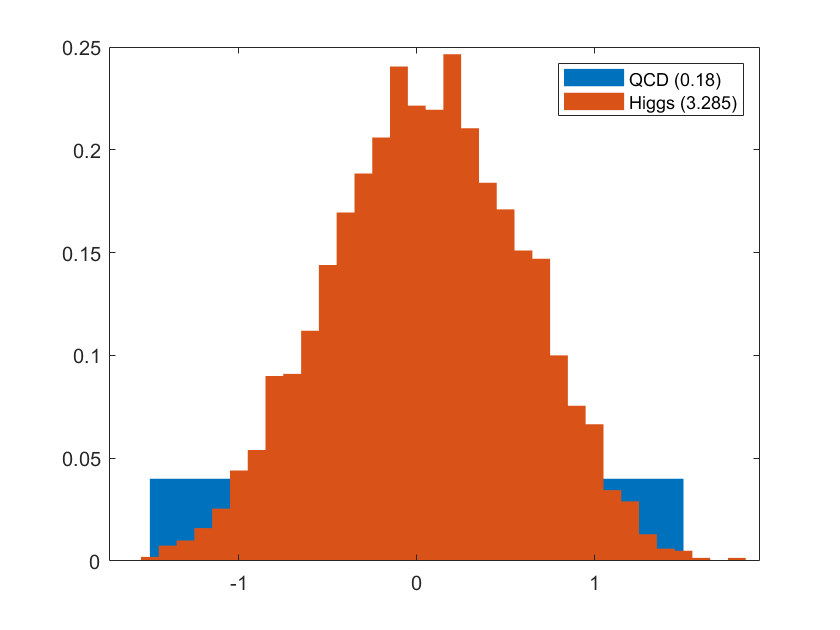

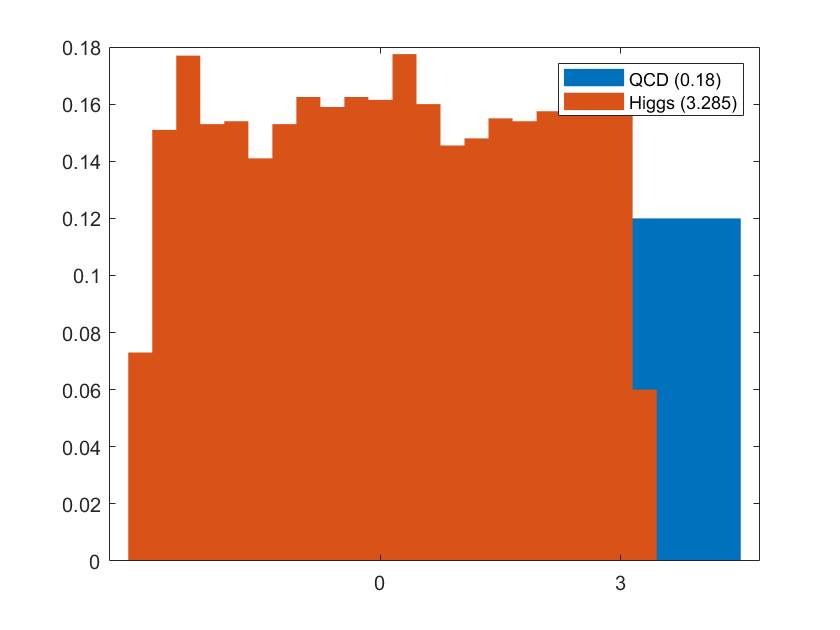

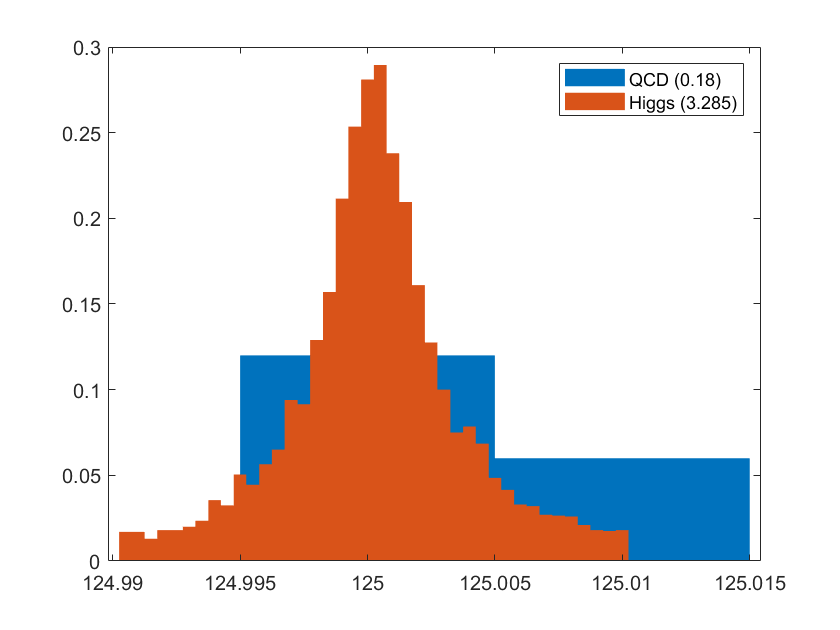

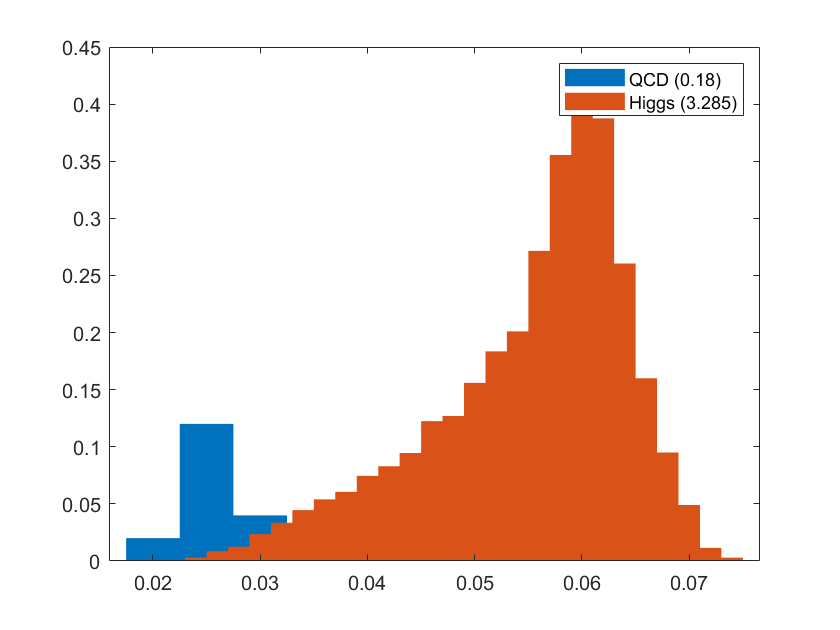

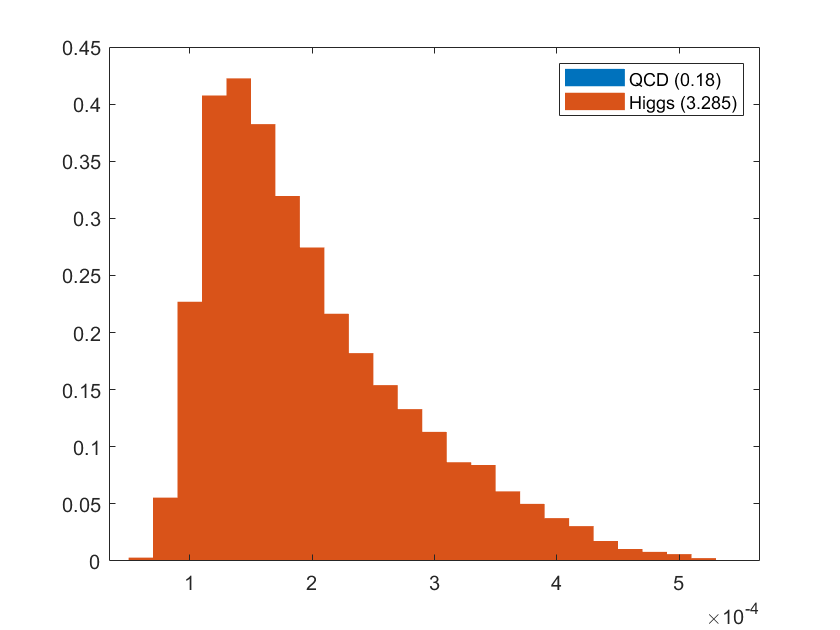

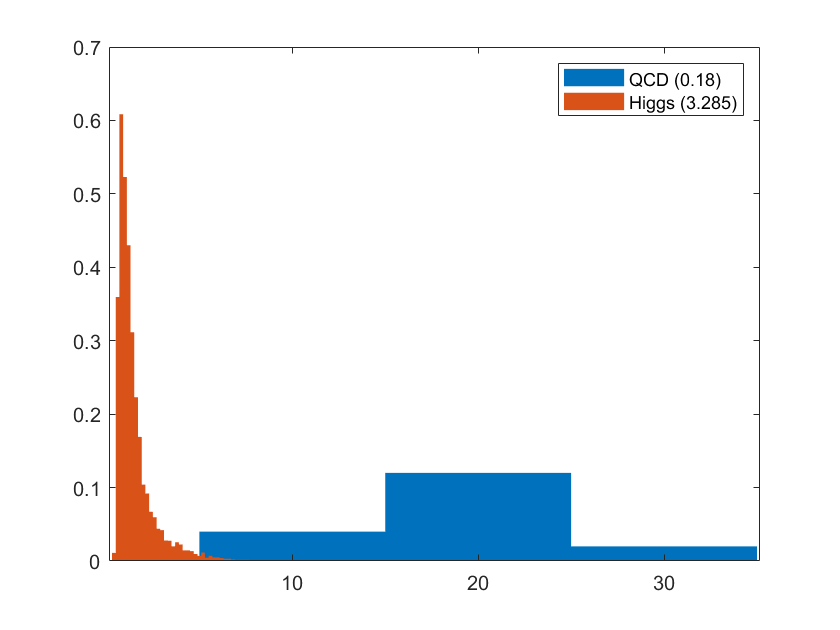

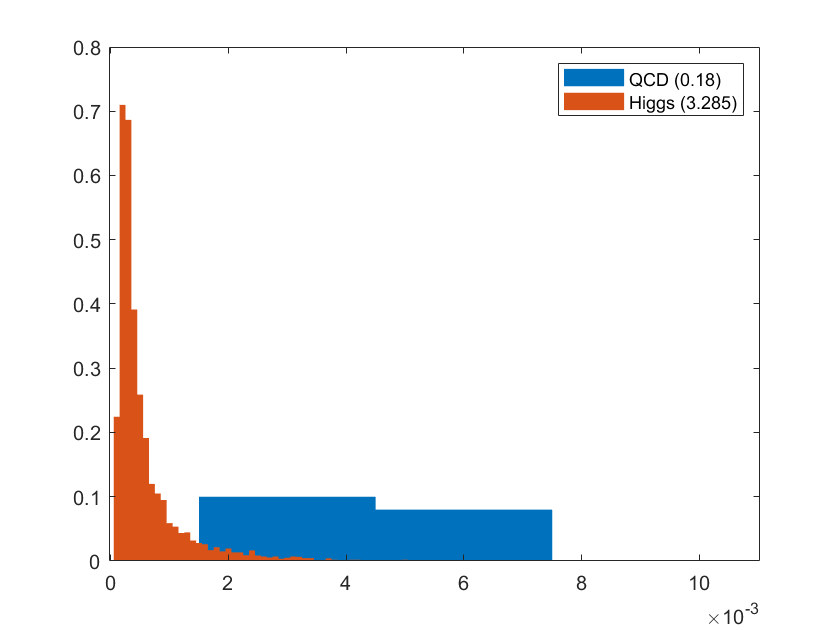

newcutsignal = signaldata1;
newcutbg = bgdata1;
lowercut = 124.99;
uppercut = 125.01;
for k = 1:numel(bgdata1(4,:))
    if signaldata1(4,k) > uppercut || signaldata1(4,k) < lowercut
        newcutsignal(:,k) = nan;
    end
    if bgdata1(4,k) > uppercut || bgdata1(4,k) < lowercut
        newcutbg(:,k) = nan;
    end
end

for k = 1:14   
    signal = newcutsignal(k,:);
    bg = newcutbg(k,:);
    f1 = figure();
    f2 = figure("Visible","off");
    h = histogram(signal,"Normalization","pdf");
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
    hold on;
    h2 = histogram(bg,"Normalization","pdf");
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
    hold off;
        
    figure(f1);
    bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
    hold on;
    bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
    legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
    hold off;
end

Running into the same issues when things are too small. Not enough background to work with. Some plots show background centered away which can be cut further while preserving much of the true Higgs distribution, but at this point removing more gets us closer to removing the background entirely which doesn't make sense and would cause division by zero for our n over root n calculation we've been doing. Something is clearly wrong with this approach.

## Problem 4

Using multiple features may not be necessary because when we've cut the background down to such a narrow region around mass 125 MeV the events are very likely (7.5-ish) to be the signal.